# Exam A Question 3

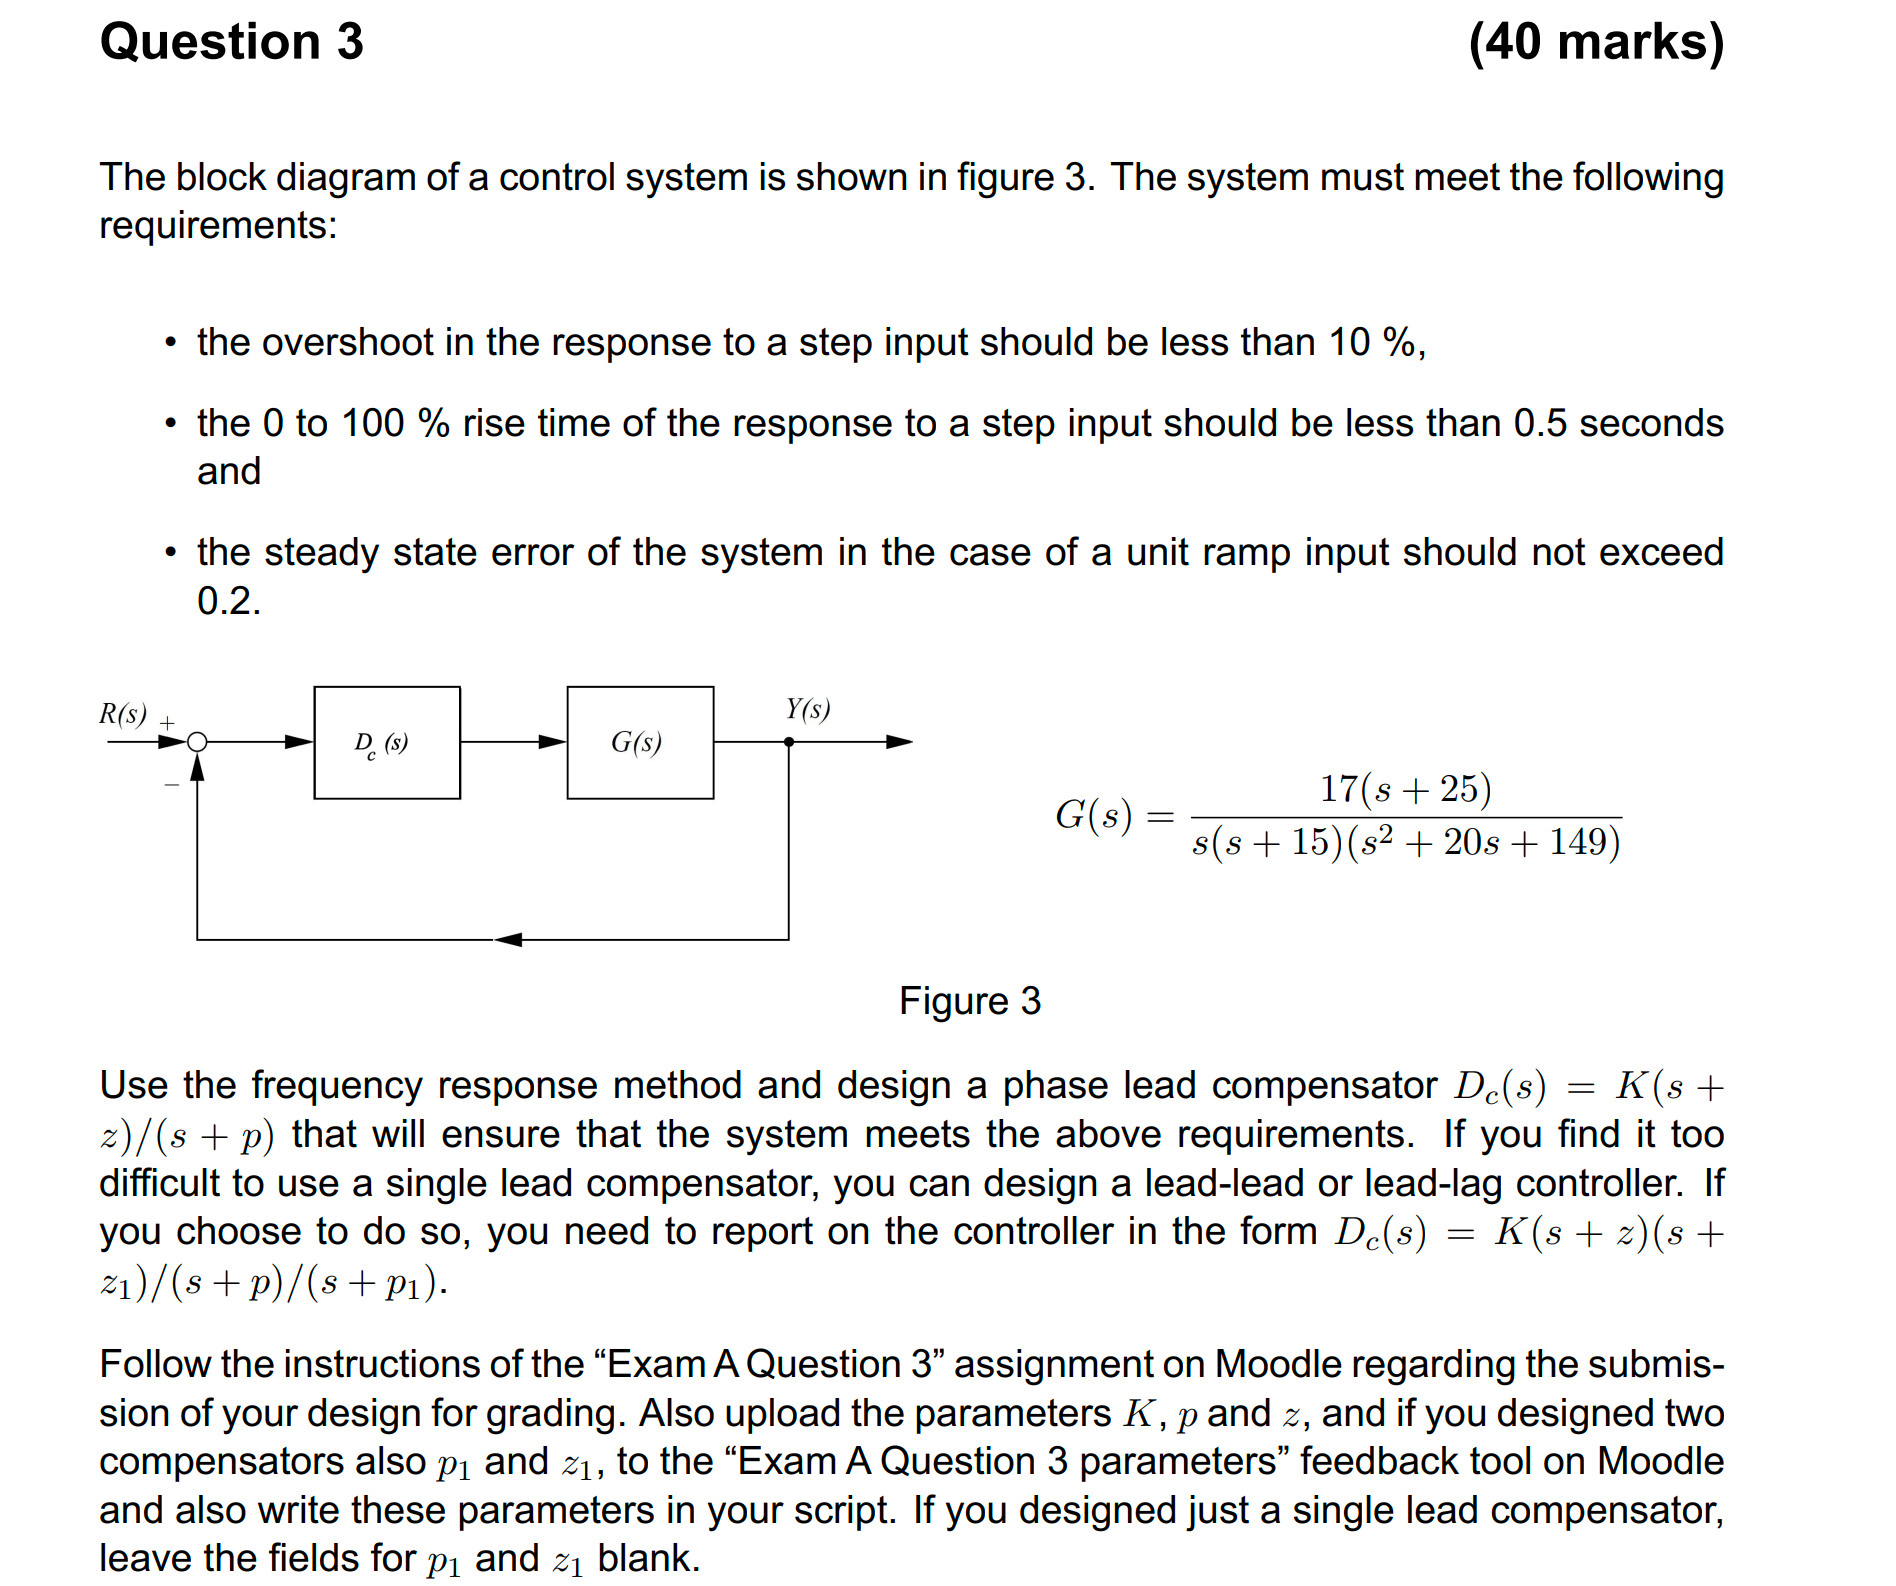

since overshoot $M_p \le 10%$, from Franklin Figure 3.24, P161, we get $\zeta =0\ldotp 6$.

rise time $t_r \le 0\ldotp 5$.


$$e_{\mathrm{ss}} =\frac{A}{K_v }\le 0\ldotp 2\to K_V \ge 5$$



$$K_v =\lim_{s\to 0} {\textrm{KD}}_c \left(s\right)G\left(s\right)=\frac{17*25}{15*149}=0\ldotp 1902$$


we assume $D_c \left(s\right)$=1

The gain is smaller than a factor of 26.3

Relation between PM and $\zeta$is


$$\textrm{PM}=\tan^{-1} \left\lbrack \frac{2\zeta }{\sqrt{\sqrt{1+4\zeta^4 }-2\zeta^2 }}\right\rbrack =59\ldotp 1873\;$$


clearvars, clc, close all

Gpoles = [0 -15 -10+1j*7,-10-1j*7]

Gpoles =    0.0000 + 0.0000i -15.0000 + 0.0000i -10.0000 + 7.0000i -10.0000 - 7.0000i


G = zpk([-25],Gpoles,17.0)


G =
 
          17 (s+25)
  --------------------------
  s (s+15) (s^2 + 20s + 149)
 
Continuous-time zero/pole/gain model.


zeta = 0.6

zeta = 0.6000

K1 = 26.3

K1 = 26.3000


% first plot the uncompensated step response 
T = feedback(K1*G,1)


T =
 
                 447.1 (s+25)
  ------------------------------------------
  (s^2 + 29.56s + 242) (s^2 + 5.442s + 46.2)
 
Continuous-time zero/pole/gain model.


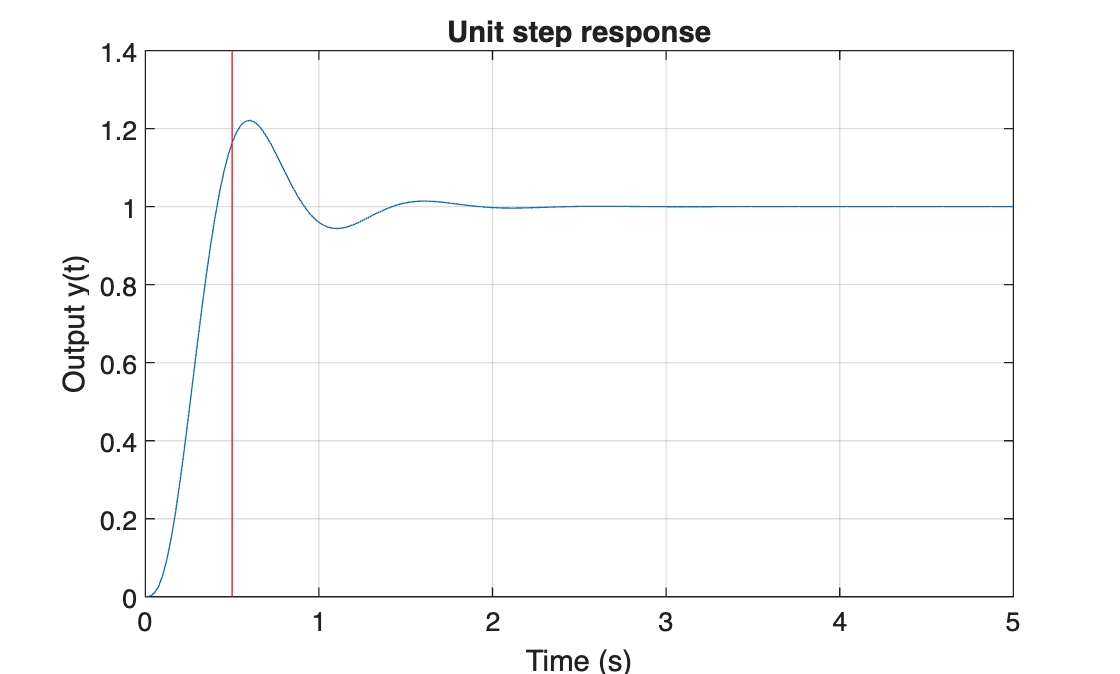

tt = linspace(0.0,5.0,200);
y = step(T,tt);
figure(1)
plot(tt,y)
hold on
%plot([tt(1), tt(end)],[1.05, 1.05],'g')
%plot([tt(1), tt(end)],[1.02, 1.02],'r')
%plot([tt(1), tt(end)],[0.98, 0.98],'r')
plot([0.5,0.5],[0,1.4],'r')
grid on
xlabel('Time (s)')
ylabel('Output y(t)')
title('Unit step response')

We can see the rising time and overshoot in figure 1 doesn't meet the requirements.

desired_PM = rad2deg(atan((2*zeta)/ sqrt(sqrt(1+4*zeta^4)-2*zeta^2)))

desired_PM = 59.1873

figure(2)
omega = logspace(0,2,400);
[mag1,phase1] = bode(K1*G,omega);
mag1 = squeeze(mag1);
phase1 = squeeze(phase1);
subplot(2,1,1),semilogx(omega,20*log10(mag1))
xlabel('Angular frequency \omega (rad/s)'),ylabel('20log|G(\omega)|')
hold on
grid on
title('Plant (open loop) transfer function bode diagram')
subplot(2,1,2),semilogx(omega,phase1)
xlabel('Angular frequency \omega (rad/s)'),ylabel('\phi')
grid on
[Gm,Pm,omegcp,omegcg] = margin(K1*G);
dBGm = 20*log10(Gm);
disp(['System phase margin (degrees): ',num2str(Pm)])

System phase margin (degrees): 47.6466


disp(['System cross over angular frequency (rad/s): ',num2str(omegcg)])

System cross over angular frequency (rad/s): 4.5988


disp(['System gain margin (dB): ',num2str(dBGm)])

System gain margin (dB): 10.1989


disp(['System Phase Crossover Frequency (rad/s):',num2str(omegcp)])

System Phase Crossover Frequency (rad/s):10.2561


ince the phase margin of the gain adjusted uncompensated system is about $48\degree$ degrees but we need $60\degree$, we would like to add about 12 degrees of additional phase to the phase diagram at the angular frequency where the compensated loop transfer function logarithmic gain curve will drop through 0 dB. It is suggested that we add something as a measure of safety, so, I decided to start off my design iterations with $\phi_{\max } =27\degree$.

phi = deg2rad(25)

phi = 0.4363

alpha = (1-sin(phi))/(1+sin(phi))

alpha = 0.4059

disp("To have phi_max = 27 degrees, we need alpha to be "+num2str(alpha))

To have phi_max = 27 degrees, we need alpha to be 0.40586


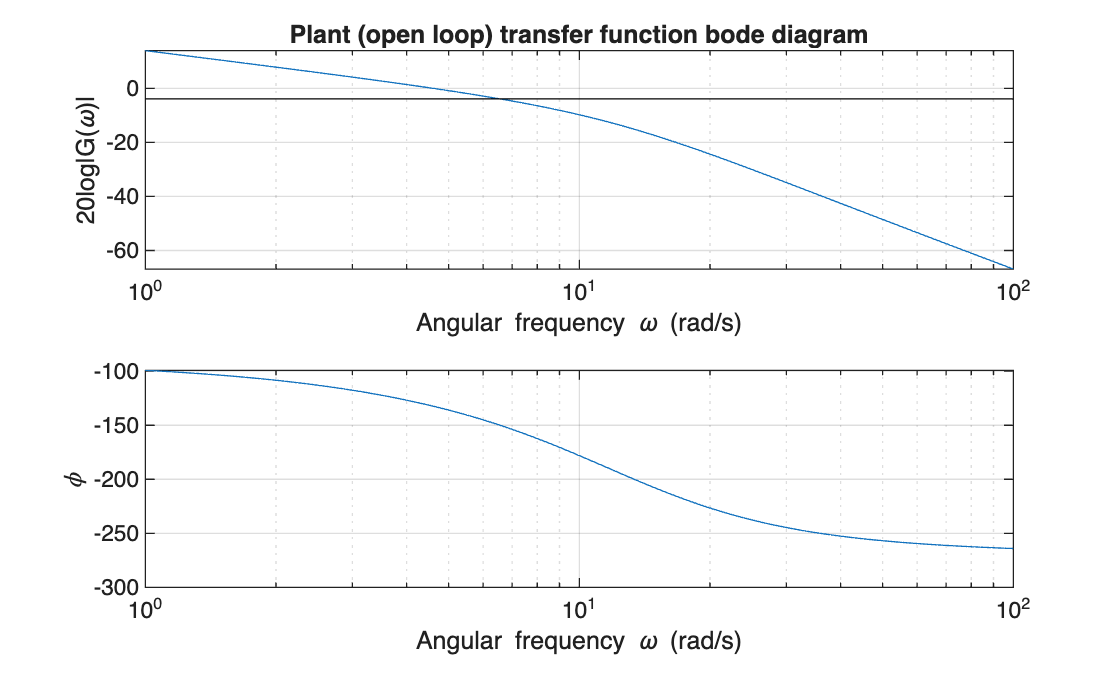

bb = 10*log10(alpha);
figure(2)
subplot(2,1,1),semilogx([omega(1), omega(end)],[bb, bb],'k')

$w_{\max } \approx 6\ldotp 3\frac{\textrm{rad}}{s}$ read from the bode diagram


$$T_D =\frac{1}{\omega_{\max } \sqrt{\alpha }}$$


and Then the compensator is calculated as: $D_C =\frac{T_D s+1}{\alpha \;T_D s+1}$    

omegam = 6.3

omegam = 6.3000

%omegam = ginput(1);
%omegam = omegam(1);
disp("Compensator geometric mean frequency omegam = "+num2str(omegam)...
+" rad/s")

Compensator geometric mean frequency omegam = 6.3 rad/s


TD = 1/omegam/sqrt(alpha);
Dc = tf([TD, 1],[alpha*TD, 1])


Dc =
 
  0.2492 s + 1
  ------------
  0.1011 s + 1
 
Continuous-time transfer function.


disp("Lead compensator zero = -"+num2str(1/TD)+"rad/s")

Lead compensator zero = -4.0135rad/s


disp("Lead compensator pole = -"+num2str(1/(alpha*TD))+"rad/s")

Lead compensator pole = -9.889rad/s


disp('Compensated loop transfer function:')

Compensated loop transfer function:


Gt = Dc*K1*G


Gt =
 
        1101.6 (s+4.014) (s+25)
  ------------------------------------
  s (s+9.889) (s+15) (s^2 + 20s + 149)
 
Continuous-time zero/pole/gain model.


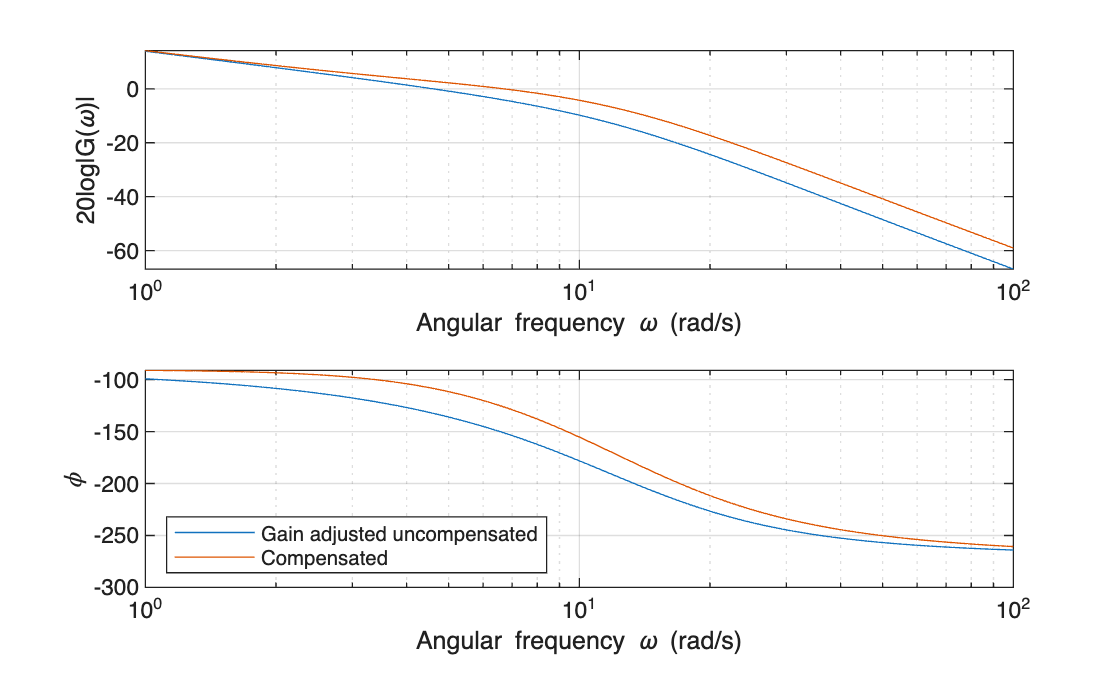



figure(3)
title('Loop transfer functions Bode diagrams')
[mag2,phase2] = bode(Gt,omega);
mag2 = squeeze(mag2);
phase2 = squeeze(phase2);
subplot(2,1,1)
semilogx(omega,20*log10(mag1))
hold on
semilogx(omega,20*log10(mag2))
hold off
grid on
xlabel('Angular frequency \omega (rad/s)'),ylabel('20log|G(\omega)|')
subplot(2,1,2)
semilogx(omega,phase1)
hold on
semilogx(omega,phase2)
hold off
grid on
xlabel('Angular frequency \omega (rad/s)'),ylabel('\phi')
legend('Gain adjusted uncompensated','Compensated','Location','southwest')


[Gm,Pm,omegcp,omegcg] = margin(Gt);
dBGm = 20*log10(Gm);
disp(['Compensated system phase margin (degrees): ',num2str(Pm)])

Compensated system phase margin (degrees): 53.8536


disp(['Compensated system cross over angular frequency (rad/s): ',...
num2str(omegcg)])

Compensated system cross over angular frequency (rad/s): 6.687


disp(['Compensated system gain margin (dB): ',num2str(dBGm)])

Compensated system gain margin (dB): 8.7785


disp(['Compensated system gain margin cross over angular frequency (rad/s): '...
,num2str(omegcp)])

Compensated system gain margin cross over angular frequency (rad/s): 13.3474


when $\omega_{\max } =6\ldotp 3\;\frac{\textrm{rad}}{s}$ the PM doesn't meet the requirement. Then we iterate the $\omega_{\max } \;$to 7.5 rad/s

omegam = 9 %rad/s

omegam = 9

disp("Compensator geometric mean frequency omegam = "+num2str(omegam)...
+" rad/s")

Compensator geometric mean frequency omegam = 9 rad/s


TD = 1/omegam/sqrt(alpha);
Dc = tf([TD, 1],[alpha*TD, 1])


Dc =
 
  0.1744 s + 1
  -------------
  0.07079 s + 1
 
Continuous-time transfer function.


disp("Lead compensator zero = -"+num2str(1/TD)+"rad/s")

Lead compensator zero = -5.7336rad/s


disp("Lead compensator pole = -"+num2str(1/(alpha*TD))+"rad/s")

Lead compensator pole = -14.1272rad/s


disp('Compensated loop transfer function:')

Compensated loop transfer function:


Gt = Dc*K1*G


Gt =
 
        1101.6 (s+5.734) (s+25)
  ------------------------------------
  s (s+14.13) (s+15) (s^2 + 20s + 149)
 
Continuous-time zero/pole/gain model.


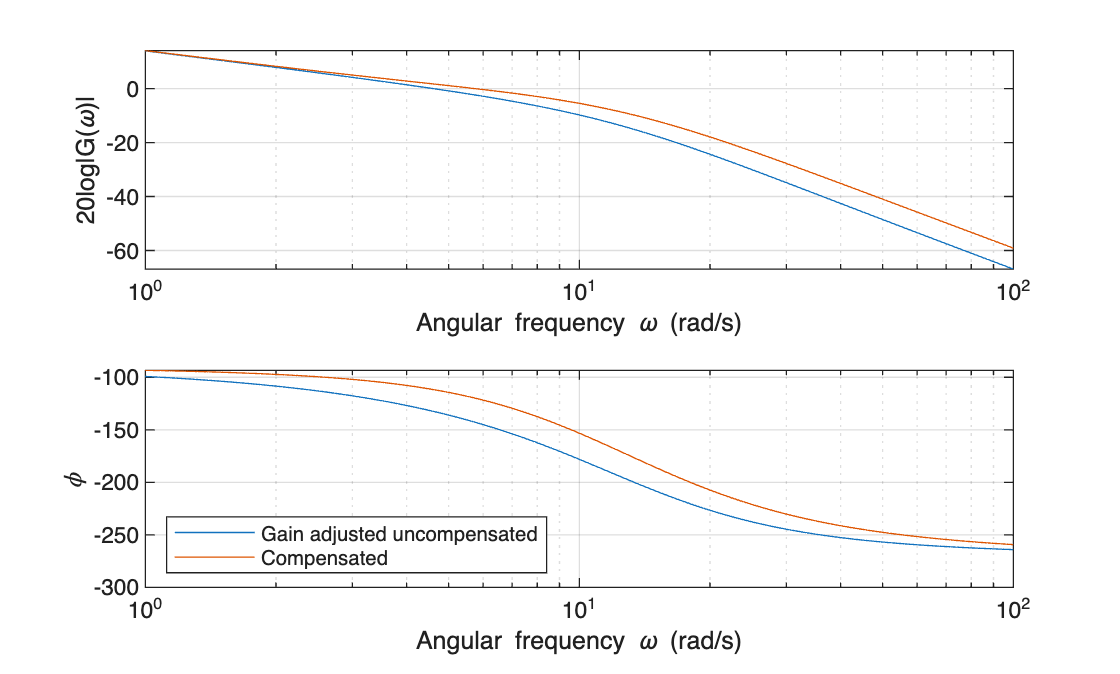



figure(4)
title('Loop transfer functions Bode diagrams')
[mag2,phase2] = bode(Gt,omega);
mag2 = squeeze(mag2);
phase2 = squeeze(phase2);
subplot(2,1,1)
semilogx(omega,20*log10(mag1))
hold on
semilogx(omega,20*log10(mag2))
hold off
grid on
xlabel('Angular frequency \omega (rad/s)'),ylabel('20log|G(\omega)|')
subplot(2,1,2)
semilogx(omega,phase1)
hold on
semilogx(omega,phase2)
hold off
grid on
xlabel('Angular frequency \omega (rad/s)'),ylabel('\phi')
legend('Gain adjusted uncompensated','Compensated','Location','southwest')


[Gm,Pm,omegcp,omegcg] = margin(Gt);
dBGm = 20*log10(Gm);
disp(['Compensated system phase margin (degrees): ',num2str(Pm)])

Compensated system phase margin (degrees): 60.2665


disp(['Compensated system cross over angular frequency (rad/s): ',...
num2str(omegcg)])

Compensated system cross over angular frequency (rad/s): 5.7339


disp(['Compensated system gain margin (dB): ',num2str(dBGm)])

Compensated system gain margin (dB): 10.5517


disp(['Compensated system gain margin cross over angular frequency (rad/s): '...
,num2str(omegcp)])

Compensated system gain margin cross over angular frequency (rad/s): 13.9456


Now the PM meet the requirements

disp("Compensated system transfer function"+...
"(i.e., the closed loop transfer function):")

Compensated system transfer function(i.e., the closed loop transfer function):


T2 = feedback(Gt,1)


T2 =
 
                 1101.6 (s+25) (s+5.734)
  -----------------------------------------------------
  (s+4.103) (s^2 + 37.78s + 385) (s^2 + 7.247s + 99.98)
 
Continuous-time zero/pole/gain model.


y2 = step(T2,tt);

yfinal = y2(end);
[ypeak, ipeak] = max(y2);
tpeak = tt(ipeak);
Mp = (ypeak - yfinal)/yfinal*100;      % overshoot in %

idx = find(y2 >= 0.999*yfinal, 1);     % first time reaching 100%
tr = tt(idx);

disp("Overshoot Mp = " + num2str(Mp) + " %  (peak at t = " + num2str(tpeak) + " s)")

Overshoot Mp = 9.7424 %  (peak at t = 0.42714 s)


disp("Rise time (0-100%) = " + num2str(tr) + " s")

Rise time (0-100%) = 0.35176 s



if Mp <= 10
    disp("Overshoot requirement (<=10%): PASS")
else
    disp("Overshoot requirement (<=10%): FAIL")
end

Overshoot requirement (<=10%): PASS



if tr <= 0.5
    disp("Rise time requirement (<=0.5s): PASS")
else
    disp("Rise time requirement (<=0.5s): FAIL")
end

Rise time requirement (<=0.5s): PASS


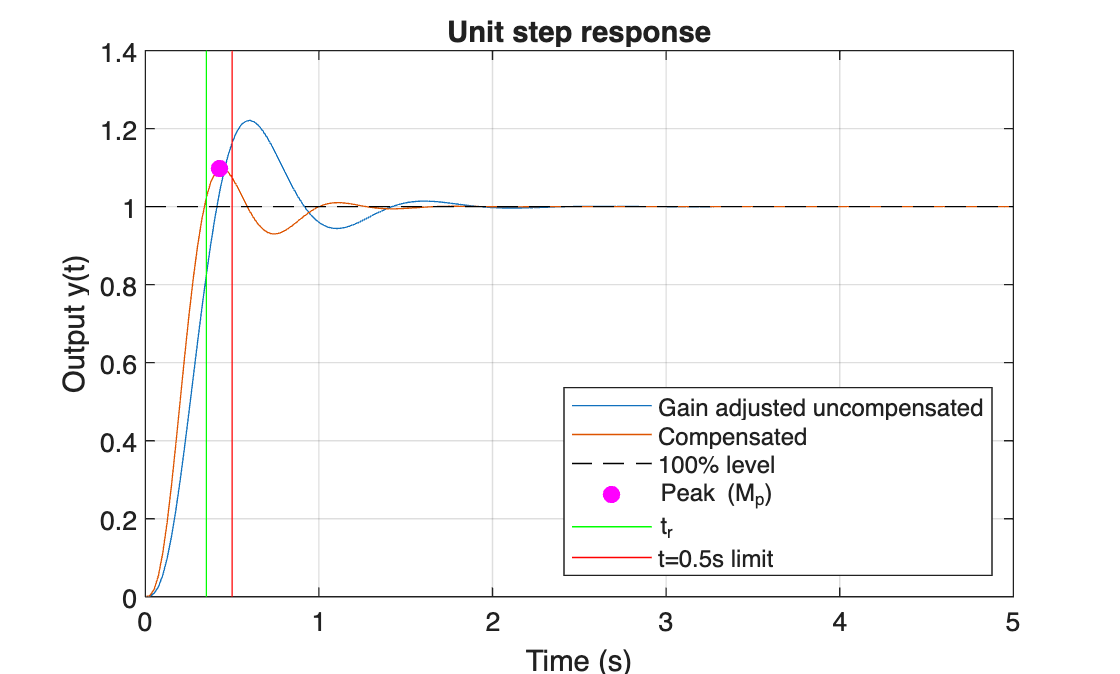


figure(5)
plot(tt,y,tt,y2)
hold on
plot([tt(1), tt(end)],[1.0, 1.0],'k--')         % 100% reference
plot(tpeak, ypeak,'mo','MarkerFaceColor','m')   % mark overshoot peak
plot([tr, tr],[0, 1.4],'g')                     % rise time marker
plot([0.5, 0.5],[0, 1.4],'r')                   % 0.5s spec line
legend('Gain adjusted uncompensated','Compensated','100% level','Peak (M_p)','t_r','t=0.5s limit','location','southeast')
grid on
xlabel('Time (s)'), ylabel('Output y(t)')
title('Unit step response')
hold off